controlParamsDD = Simulink.data.dictionary.open('controlVariablesData.sldd');
sectControl = getSection(controlParamsDD,'Design Data');
% Dmin = getValue(getEntry(sectControl,'D_min'));
Dmin = 20;

x = [0:0.01:1];
b = 0.01;
y =  Dmin/100*tanh(x/b)+(100-Dmin)/100*x;
x1 = x + 0.01;
y1 = (log(x1)-log(x1(1)))/(log(x1(end))-log(x1(1)))

y1 =          0    0.1502    0.2380    0.3004    0.3487    0.3882    0.4216    0.4506    0.4761    0.4989    0.5196    0.5384    0.5558    0.5718    0.5868    0.6008    0.6139    0.6263    0.6380    0.6491    0.6597    0.6698    0.6794    0.6886    0.6975    0.7060    0.7141    0.7220    0.7296    0.7370    0.7441    0.7510    0.7576    0.7641    0.7704    0.7765    0.7824    0.7882    0.7938    0.7993    0.8047    0.8099    0.8150    0.8200    0.8248    0.8296    0.8342    0.8388    0.8433    0.8477


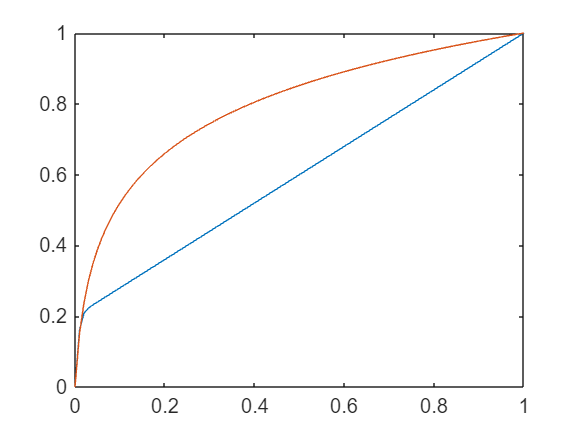


figure()
plot(x,y,x,y1)

Kp = 35

Kp = 35

Ki = 0.5

Ki = 0.5000

Ts = 0.005

Ts = 0.0050

num_pid = [Kp Ki*Ts-Kp]

num_pid =    35.0000  -34.9975


den_pid = [1 -1]

den_pid =      1    -1


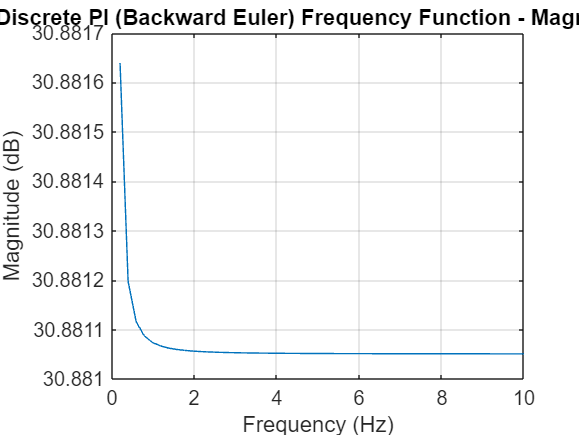


Fs = 1/Ts;
N = 1024; 

[H, W] = freqz(num_pid, den_pid, N, 'whole', Fs);

figure
plot(W(1:N/2+1), 20*log10(abs(H(1:N/2+1))));
grid on;
title('Discrete PI (Backward Euler) Frequency Function - Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 10])

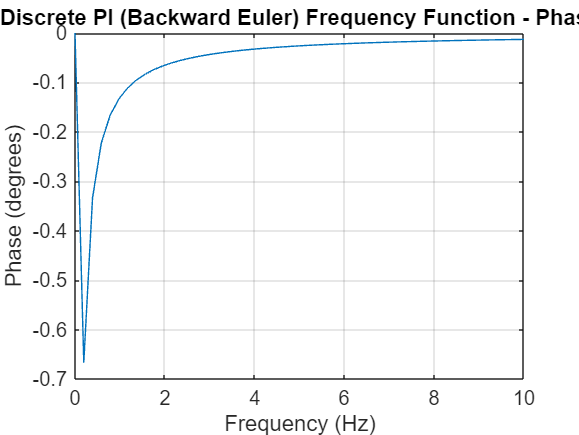


figure
plot(W(1:N/2+1), unwrap(angle(H(1:N/2+1)))*180/pi);
grid on;
title('Discrete PI (Backward Euler) Frequency Function - Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
xlim([0 10])